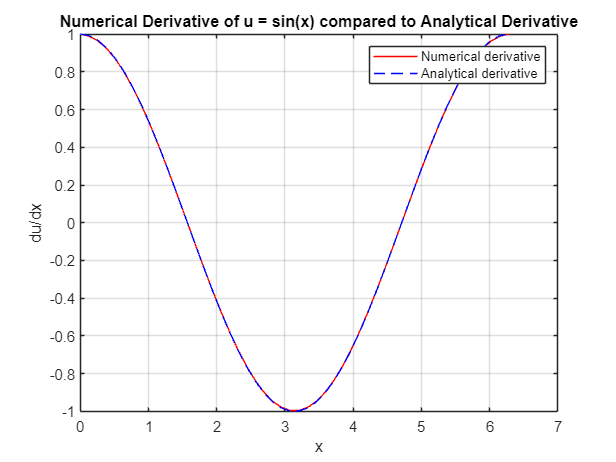

clc;
clear;

% Example usage for a small vector
x = linspace(0, 2*pi, 50); % Smaller vector
h = x(2) - x(1);
u = sin(x);

% Call the function to calculate the first derivative with specified points
du_dx = calculateGeneralDerivative(u, h, 1, 4, 4); % Function will adjust if needed
% Plot the numerical derivative and analytical derivative
figure;
plot(x, du_dx, 'r-', x, cos(x), 'b--');
xlabel('x');
ylabel('du/dx');
title('Numerical Derivative of u = sin(x) compared to Analytical Derivative');
legend('Numerical derivative', 'Analytical derivative');
grid on;

function MyDiff = calculateGeneralDerivative(u, h, derivativeOrder, forwardPoints, backwardPoints)
    % General function to calculate the numerical derivative of a vector u using spacing h.
    % This version adjusts forward and backward points if u has less length than specified points.
    
    % For second derivative to be happened n must be minimum n = 3

    n = length(u);
    MyDiff = zeros(size(u));

    % Adjust forward and backward points based on the length of u
    if n < forwardPoints
        forwardPoints = n;
    end
    if n < backwardPoints
        backwardPoints = n;
    end

    if derivativeOrder == 1
        % Apply forward difference at the first point
        if forwardPoints == 2
            MyDiff(1) = (u(2) - u(1)) / h;
        elseif forwardPoints == 3
            MyDiff(1) = (-3*u(1) + 4*u(2) - u(3)) / (2*h);
        elseif forwardPoints >= 4
            MyDiff(1) = ( (-11/6)*u(1) + (3)*u(2) + (-3/2)*u(3) + (1/3)*u(4) ) / h;

        end

        % Central difference for intermediate points
        for i = 2:n-1
            MyDiff(i) = (u(i+1) - u(i-1)) / (2*h);
        end

        % Apply backward difference at the last point
        if backwardPoints == 2
            MyDiff(n) = (u(n) - u(n-1)) / h;
        elseif backwardPoints == 3
            MyDiff(n) = (3*u(n) - 4*u(n-1) + u(n-2)) / (2*h);
        elseif backwardPoints >= 4
            MyDiff(n) = ( (11/6)*u(n) + (-3)*u(n-1) + (3/2)*u(n-2) + (-1/3)*u(n-3) ) / h;
        end

    elseif derivativeOrder == 2

        if n > 3

            % Second derivative calculations
            for i = 2:n-1
                MyDiff(i) = (u(i+1) - 2*u(i) + u(i-1)) / (h^2);
            end
    
            % Forward difference for second derivative
    
            if forwardPoints == 3
                MyDiff(1) = ( u(1) - 2*u(2) + u(3) ) / (h^2);
    
            elseif forwardPoints >= 4
                MyDiff(1) = (2*u(1) - 5*u(2) + 4*u(3) - u(4)) / (h^2);
            end
    
    
            % Backward difference for second derivative
    
            if backwardPoints == 3
                MyDiff(n) = (u(n) - 2*u(n-1) + u(n-2)) / (h^2);
            elseif backwardPoints >= 4
                MyDiff(n) = (2*u(n) - 5*u(n-1) + 4*u(n-2) - u(n-3)) / (h^2);
            end

        else
            disp("Number of points are very less for applying Second Derivative")
        end

    end
end
